# Test Script for the STM32 DSP Pipeline

Author: Michael Noyce

Description: Compares the processing done in MATLAB vs the signal processing done on the STM32. 

## Calibration Function 

Textfile = load("calibratedOutput.txt")

Textfile =     0.0754
    0.0588
    0.0778
    0.0327
    0.0825
    0.0825
    0.0375
    0.1110
    0.0754
    0.0920


writematrix(Textfile, "calibratedOutput.csv");
calibratedOutput = readtable("calibratedOutput.csv");

T = 0.01;
N = height(calibratedOutput(:,1))

N = 1000

t = (0:N-1)*T;        % Time vector

figure();
plot(t, accZCal(20000:20000+N-1, 1), t, calibratedOutput{:, 1});
title('IMU Platform Calibrated acceleration values in m/s^2')
legend("X", "Y", "Z")

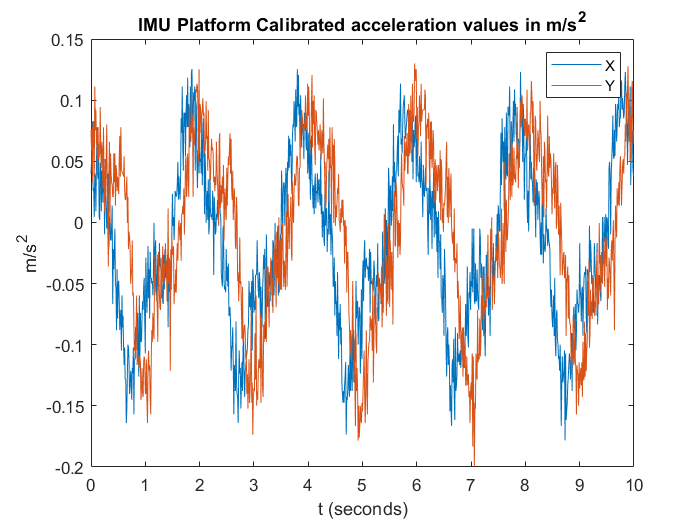

xlabel('t (seconds)')
ylabel('m/s^2')

## Detrend Function 

Textfile = load("detrendedOutput.txt")

Textfile =     0.0850
    0.0684
    0.0873
    0.0422
    0.0920
    0.0919
    0.0468
    0.1203
    0.0847
    0.1012


writematrix(Textfile, "detrendedOutput.csv");
detrendedOutput = readtable("detrendedOutput.csv");

T = 0.01;
N = height(detrendedOutput(:,1))

N = 1000

t = (0:N-1)*T;        % Time vector

figure();
plot(t, accZ(1, 20000:20000+N-1), t, detrendedOutput{:, 1});
title('IMU Platform detrended acceleration values in m/s^2')
legend("X", "Y", "Z")

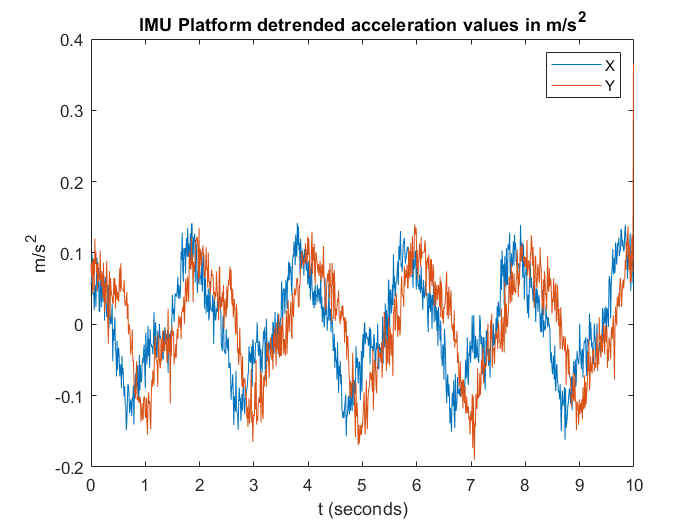

xlabel('t (seconds)')
 ylabel('m/s^2')